初版：2021年12月25日

# シミュレーション　講義ノート No.5

#### 藤原　哉

#### 農林中央金庫

### 確率微分方程式のシミュレーションでの分散逓減法

確率微分方程式に解析解があれば、講義ノート No.2、No.3で説明した分散逓減法がそのまま適用可能である。

離散化してシミュレーションする場合の分散逓減法の適用は以下のようになる。

- Antithetic Sampling： パス生成の時に適用可能 ( $W_{t+\Delta t} - W_t$ の実現値が $x$のとき、 $-x$となるパスも同時に生成する)

- Importance Sampling：確率過程の測度変換により可能（Radon-Nikodym微分のシミュレーションも必要）

- Control Variate：そのまま適用可能

- Stratified Sampling／Latin Hypercubic Method：適切な領域分割が一般に難しく、適用が困難

- 準モンテカルロ法：パス生成の時に適用可能

- Multilevel Monte Carlo: 計算コストと誤差のトレードオフを考慮して複数の近似レベルの結果を組み合わせる

#### 1.  Importance Sampling：Girsanovの定理の利用

 確率微分方程式がブラウン運動で表されているときGirsanovの定理を利用すると推定値の分散を小さくすることが出来る場合がある。

**Girsanovの定理**

ある確率空間 $\left(\Omega, \mathcal{F}, \{\mathcal{F}_t \},\mathbb{P}\right)$での標準ブラウン運動を $W_t$とする。

任意の$A \in \mathcal{F}_t$に対して

 
$$\mathbb{Q}\left[A\right] = \mathbb{E}^{\mathbb{P}}\left[ \mathbb{1}_{A} Y_t \right]$$



$$Y_t = {\rm e}^{ \int_0^t \theta_s {\rm d}W_s - \int_{0}^{t}{ \ \frac{ \theta^2_s }{ 2 }} {\rm d} s}$$


として確率測度 $\mathbb{Q}$を定める。このとき $\mathbb{Q}$のもとでのブラウン運動を $W_t^*$とすると


$${\rm d}W_t^* = -\theta_t {\rm d} t + {\rm d}W_t$$


となる。

**Girsanovの定理を用いたImportance Sampling**

$\left(\Omega, \mathcal{F}, \{\mathcal{F}_t \},\mathbb{P}\right)$のもとで $W_t$を標準ブラウン運動として$X_t$が以下の確率微分方程式に従っているとする。


$${\rm d}X_t = \mu_t {\rm d}t + \sigma_t {\rm d}W_t$$


また、$\mathbb{Q}$のもとでの標準ブラウン運動を $W_t^*$として


$${\rm d}X_t = r_t {\rm d}t + \sigma_t {\rm d}W_t^*$$


に従うとする。このときGirsanovの定理より


$${\rm d}W_t^* = -\theta_t {\rm d} t + {\rm d}W_t$$



$$\theta_t = \frac{r_t - \mu_t}{\sigma_t}$$


となる。これより


$$\mathbb{E}^{\mathbb{Q}} \left[ f(X_T) \right] = \mathbb{E}^{\mathbb{P}} \left[ f(X_T) Y_T \right]$$



$$Y_T = {\rm e}^{\int_0^T \frac{r_s - \mu_s}{\sigma_s} {\rm d}W_s - \frac{1}{2} \int_0^T \left( \frac{r_s - \mu_s}{\sigma_s} \right)^2 {\rm d} s}$$


となる。よって、 $\mathbb{Q}$での期待値計算は $\mathbb{P}$のもとでのドリフト $\mu_t$を任意に定めて対応する $Y_t$を用いて $\mathbb{P}$のもとでシミュレーションすることで求めることができる。

このことを利用して推定値の分散が小さくなるように$\mu_t$を選択する。

#### 例：Importance SamplingによるOTMオプションの評価

リスク中立確率測度 $\mathbb{Q}$のもとで株価が以下の確率微分方程式に従っているとする。


$$\frac{{\rm d}S_t}{S_t} = r {\rm d} t + \sigma {\rm d}W_t$$


$r,\sigma$は定数とする。 このとき、ストライク $K$ 、満期 $T$のコールオプションの価格 $V_0$を評価する。


$$V_0 = {\rm e}^{-r T} \mathbb{E}^{\mathbb{Q}}\left[ \left(S_T - K \right)^{+} \right]$$


$r = 0.0, \sigma = 0.3,S_0=100$とし、満期 $T=1$,ストライク $K = 200$のオプション価格をシミュレーションで求めて解析解と比較する。

$S_T > 200$となる確率は $0.7\%$であるのでシミュレーションで $S_T > 200$となるパスの数が少ない。そのために推定値の分散が大きくなってしまう。

$S_T > 200$となる確率が $50\%$になるような確率測度 $\mathbb{P}$を用いて評価することを考える。

$\mathbb{P}$のもとでのドリフト項を $\mu$、ブラウン運動を $W_t^*$とすると


$$\frac{{\rm d}S_t}{S_t} = \mu {\rm d}t + \sigma {\rm d}W_t^*$$


となる。Girsanovの定理より


$$Y_t = {\rm e}^{\theta W_t^* - \frac{1}{2}\theta^2 t}$$



$${\rm d}W_t = -\theta_t {\rm d} t + {\rm d}W_t^*$$



$$\theta_t = \frac{r_t - \mu_t}{\sigma_t}$$


となるので、これより


$$V_0 = {\rm e}^{-r T} \mathbb{E}^{\mathbb{Q}}\left[ \left(S_T - K \right)^{+} \right] = {\rm e}^{-rT} \mathbb{E}^{\mathbb{P}}\left[\left( S_T - K \right)^+ Y_T \right]$$


として $\mathbb{P}$のもとでシミュレーションを行う。このとき $\mathbb{P} \left( S_T \ge K) = 0.5$となる$\mu$は、$S_T = S_0 {\rm e}^{ \left( \mu - \frac{1}{2}\sigma^2 \right) T + \sigma W_T}$であるので、


$$\mu = \frac{1}{T} \log\left( \frac{K}{S_0} \right) + \frac{1}{2}\sigma^2$$


とすればよい。また、


$$\theta = \frac{r-\mu}{\sigma} = \frac{r}{\sigma} - \frac{1}{\sigma T} \log \left( \frac{K}{S_0} \right) - \frac{1}{2}\sigma$$


となる。

以下は $\mathbb{Q}$のもとで「通常」のシミュレーションで求めた場合と $\mathbb{P}$のもとでドリフトを調整してストライクを中心にパス生成したシミュレーション（つまりImportance Sampling)で求めた場合の評価誤差の比較である。この例ではImportance Samplingにより大幅に分散低減されていることがわかる。

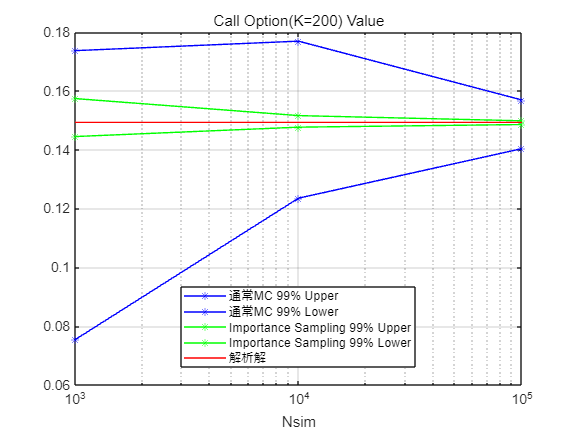

% 通常のモンテカルロシミュレーションでの評価
S0 = 100;
r = 0.0;
sig = 0.3;

K = 200;
T = 1; 

Nsims = [1000;10000;100000]; 
Nt = 10;
alp = 0.01;

% 通常のMC
lowers = zeros(size(Nsims));
uppers = zeros(size(Nsims));

% Importance Sampling
lowers2 = lowers;
uppers2 = uppers;

mu = 1/T*log(K/S0) + 1/2*sig^2;
tht = (r-mu)/sig;

for iloop = 1:size(Nsims,1)
    vs = zeros(Nt,1);
    vs2 = zeros(Nt,1);
    for jloop = 1:Nt
        WT = sqrt(T)*randn(Nsims(iloop),1);
        %　通常シミュレーション
        vs(jloop) = mean(exp(-r*T).*max(S0*exp((r-0.5*sig*sig)*T + sig*WT)-K,0.0));
        % Importance Sampling
        YT = exp(tht*WT-1/2*tht^2*T);
        vs2(jloop) = mean(exp(-r*T).*YT.*max(S0*exp((mu-0.5*sig*sig)*T + sig*WT)-K,0.0));
    end
    % 通常シミュレーション
    rsts = estConfidenceInterval(vs,alp);
    lowers(iloop) = rsts.CILower;
    uppers(iloop) = rsts.CIUpper;
    % Importance Sampling
    rsts = estConfidenceInterval(vs2,alp);
    lowers2(iloop) = rsts.CILower;
    uppers2(iloop) = rsts.CIUpper;
end

% 解析解
vana = bsModelCallPut(S0,r,sig,T,K);
vanas = vana.callValue*ones(size(Nsims));

nfig = 1;
figure(nfig); semilogx(Nsims,[uppers,lowers],'*-b');grid; hold on; title('Call Option(K=200) Value'); xlabel('Nsim');
semilogx(Nsims,[uppers2,lowers2],'*-g');
semilogx(Nsims,vanas,'-r');
legend('通常MC 99% Upper','通常MC 99% Lower','Importance Sampling 99% Upper','Importance Sampling 99% Lower','解析解','Location','best') ;
hold off;

#### 2. 準モンテカルロ法の適用

リスク中立確率測度 $\mathbb{Q}$のもとで株価が以下の確率微分方程式に従っているとする。


$$dS_t = r S_t {\rm d}t + \sigma S_t {\rm d}W_t$$


$r,\sigma$は定数とする。 このとき、ストライク $K$ 、満期 $T$のコールオプションの価格 $V_0$を評価する。


$$V_0 = {\rm e}^{-r T} \mathbb{E}^{\mathbb{Q}}\left[ \left(S_T - K \right)^{+} \right]$$


$r = 0.05, \sigma = 0.3,S_0=100$とし、満期 $T=1$,ストライク $K = 100 {\rm e}^{0.05}\simeq105.13$のオプション価格をシミュレーションで求める。

確率微分方程式はEuler法で離散近似する。


$$S_{t+\Delta t} = S_t + r S_t \Delta t + \sigma S_t (W_{t+\Delta t} - W_t)$$


ブラン運動のパス生成 $W_{0},W_{\Delta t}, W_{2 \Delta t},\cdots$を通常の乱数（疑似乱数）と準モンテカルロ(Sobol列）で行い、誤差を比較する。

Sobol列は $[0,1]$の一様分布であるので標準正規分布の逆関数を用いて標準正規に従う乱数列とする。

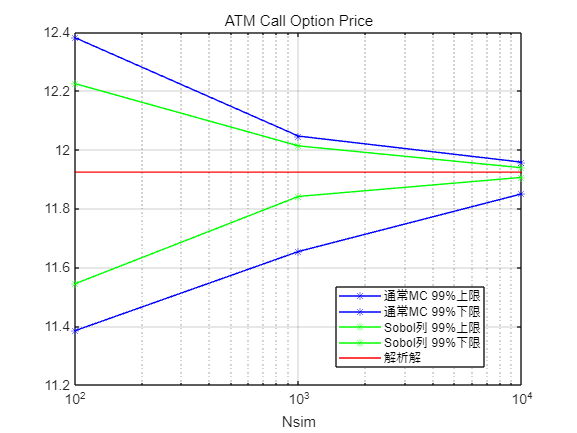

% 株価パラメータ
S0 = 100;
r = 0.05;
sig = 0.3;

% オプションパラメータ
T = 1; 
K = S0*exp(r*T); % ATM Strike

% シミュレーションパラメータ
Nsims = [100;1000;10000]; 
Nt = 100;
alp = 0.01;

Nstep = 50; % 一週間ステップ
dt = T/Nstep; 

% 通常のMC
lowers1 = zeros(size(Nsims));
uppers1 = zeros(size(Nsims));

% 準モンテカルロ
rfun = genSobolStreamFun(Nstep);
lowers2 = lowers1;
uppers2 = uppers1;

for iloop = 1:size(Nsims,1)
    Nsim = Nsims(iloop);
    vs1 = zeros(Nt,1);
    vs2 = zeros(Nt,1);
    for jloop = 1:Nt
        % 通常MC
        S1 = S0*ones(1,Nsim);
        dW1 = randn(Nstep,Nsim)*sqrt(dt); 
        % Sobol列
        S2 = S0*ones(1,Nsim); 
        dW2 = norminv(rfun(Nsim)')*sqrt(dt); % [0,1]の数列に標準正規分布の逆関数
        for kloop = 1:Nstep
            % 通常MC
            S1 = S1 + r*S1*dt + sig*S1.*dW1(kloop,:);
            % Sobol列
            S2 = S2 + r*S2*dt + sig*S2.*dW2(kloop,:); 
        end
        vs1(jloop) = exp(-r*T)*mean(max(S1-K,0));
        vs2(jloop) = exp(-r*T)*mean(max(S2-K,0));
    end
    rst = estConfidenceInterval(vs1,alp);
    lowers1(iloop) = rst.CILower;
    uppers1(iloop) = rst.CIUpper;
    rst = estConfidenceInterval(vs2,alp);
    lowers2(iloop) = rst.CILower;
    uppers2(iloop) = rst.CIUpper;
end
% 解析解
vana = bsModelCallPut(S0,r,sig,T,K);
vanas = vana.callValue*ones(size(Nsims));

nfig = 2; 
figure(nfig);semilogx(Nsims,[uppers1,lowers1],'b*-'); grid; xlabel('Nsim'); title('ATM Call Option Price');hold on;
semilogx(Nsims,[uppers2,lowers2],'g*-');semilogx(Nsims,vanas,'r-'); 
legend('通常MC 99%上限','通常MC 99%下限','Sobol列 99%上限','Sobol列 99%下限','解析解','Location','best');hold off;

#### 3. Multilevel Monte Carlo Method 

　確率過程の分散逓減法としてMultilevel Monte Carlo Method(以下はMLMCと略す）がある。MLMCはRichardson extraporationの発展系と見なされる。

まず、Richardson exptrapolationについて確認する。Richardson Extrapolationは異なる近似精度の計算を組み合わせることで誤差を低減させる。

真の値を $P$、離散近似での離散幅 $\Delta t$での評価値 $P_{\Delta t}$とし誤差は $\Delta t$のオーダーとする。


$$P_{\Delta t} - P \simeq \Delta t + O(\Delta t^2)$$


同様にして離散幅 $2\Delta t$での評価値を $P_{2\Delta t}$とすると


$$P_{2\Delta t} - P \simeq 2 \Delta t + O(\Delta t^2)$$


となる。よって、


$$2 P_{\Delta t} - P_{2\Delta t} \simeq P + O(\Delta t^2)$$


となる。

例として常微分方程式 ${\rm d} x = \kappa x {\rm d} t$をEuler法で解く場合を考える。 $\kappa$は定数である。

初期値を $x_0$として $x_T$を求める。Euler法では離散幅を $\Delta t = \frac{T}{N}$として


$$x_{n \Delta t} = x_{(n-1)\Delta t} + \kappa x_{(n-1)\Delta t} \Delta t$$



$$n = 1, \cdots, N$$



$$P_{\Delta t} = x_{N \Delta t}$$


となる。また、離散幅 $2\Delta t = \frac{T}{N/2}$として


$$x_{m 2\Delta t} = x_{(m-1) 2\Delta t} + \kappa x_{(m-1) 2\Delta t} 2 \Delta t$$



$$m=1,\cdots, M = \frac{N}{2}$$



$$P_{2\Delta t} = x_{M 2\Delta t}$$


とする。Richardson Extrapoltionによる値は $2P_{\Delta t} - P_{2\Delta t} = 2*x_{N\Delta t} - x_{M2\Delta t}$ で求められる。

$\kappa = 3, T = 1, x_0 = 1$として解析解 ${\rm e}^{3}$とRichardson Exptrapoltion、通常のEuler法、離散幅2倍でのEuler法との比較を示す。

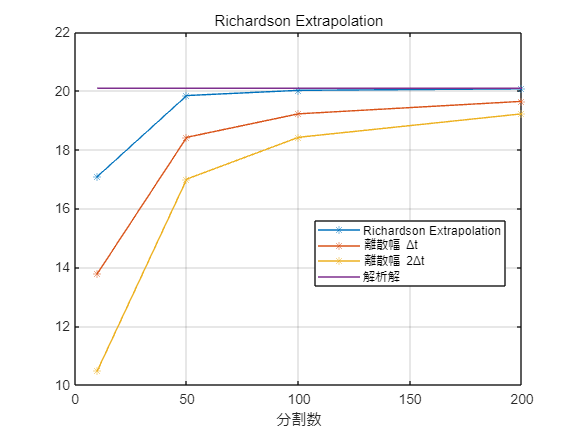

% モデルパラメータ
kappa = 3; 
T = 1; 
x0 = 1; 

% 分割数パターン
Ns = [10; 50; 100; 200]; 
vs = zeros(size(Ns,1),3);

for iloop = 1:size(Ns,1)
    % P_{\Delta t}の計算
    N = Ns(iloop); 
    dt = T/N; 
    xn = x0; 
    for jloop = 1:N
        xn = xn + kappa*xn*dt; 
    end
    % P_{2\Delta t}の計算
    M = N/2; 
    dt = T/M; 
    xm = x0; 
    for jloop=1:M
        xm = xm + kappa*xm*dt; 
    end
    vs(iloop,1) = 2*xn-xm; % Richardson Extrapolation 
    vs(iloop,2) = xn; 
    vs(iloop,3) = xm; 
end

nfig = 3; 
figure(nfig); 
plot(Ns,vs,'*-'); grid; title('Richardson Extrapolation'); xlabel('分割数'); hold on; 
plot(Ns,exp(3)*ones(size(Ns)),'-'); legend('Richardson Extrapolation', '離散幅 \Deltat', '離散幅 2\Deltat', '解析解','Location','best');
hold off; 

### MLMCの考え方

Richardson extrapolationでは２つの異なる近似精度の結果を用いて精度を向上させる。MLMCは２つ以上の異なる近似精度の結果を用いて、更に計算コストと近似精度とのトレードオフを考慮して最適な近似水準(シミュレーション回数）を決定する。

近似計算での精度を表す指標としてレベル $l$を導入し、 $l$が大きいほど精度が高いとする。例えば確率微分方程式の離散近似での時間間隔を $\frac{\Delta t}{2^l}$$\frac{\/Delta t}{2^l}$と表すと $l=0$はもともとの時間間隔$\Delta t$での近似、

$l=1$は $\frac{\Delta}{2}$と半分の時間間隔での近似を表すことになる。一般的な表記として確率変数 $P$のレベル $l$で近似計算を $P_l$と表す。

２つのレベル $l=0,1$を例としてMLMCの考え方を示す。出発は次の恒等式である。


$$\mathbb{E}\left[P_1 \right] = \mathbb{E} \left[ P_0 \right] + \mathbb{E}\left[ P_1 - P_0\right]$$


右辺のモンテカルロシミュレーションでの計算値を $\bar{P}$とすると


$$\bar{P} = \frac{1}{N_0} \sum_{n=1}^{N_0} P_0^{n} + \frac{1}{N_1} \sum_{n=1}^{N_1} \left( P_1^{n} - P_0^{n} \right)$$


となる。ただし、 $N_0,N_1$はシミュレーションの試行回数 $P_0^n, P_1^n$はレベル $l=0,1$での $n$番目の試行での実現値である。

$P_0^1,\cdots,P_0^{N_0}, P_1^1-P_0^1,\cdots,P_1^{N_1}-P_0^{N_1}$は独立同一分布として $V_0 = {\rm Var}(P_0^1),\ V_1 = {\rm Var} \left( P_1^1-P_0^1 \right)$とする。このとき


$$\epsilon^2 = {\rm Var} \left( \bar{P} \right) = \frac{1}{N_0^2} \sum_{n=1}^{N_0} {\rm Var}\left( P_0^n \right) + \frac{1}{N_1^2} \sum_{n=1}^{N_1} {\rm Var}\left( P_1^n-P_0^n \right) = \frac{1}{N_0}V_0 + \frac{1}{N_1}V_1$$


 となる。$P_0^1$の計算コストを $C_0$、 $P_1^1-P_0^1$の計算コストを $C_1$とすると $\bar{P}$の計算コスト $C\left( \bar{P} \right)$は


$$C\left( \bar{P} \right) = N_0 C_0 + N_1 C_1$$


となる。MLMCでは分散 $\varepsilon^2$を一定として計算コストを最小化するように試行回数 $N_0, N_1$を決める。つまり、次のような制約条件付き最小化問題を解く


$$\min_{N_0,N_1} \left( N_0 C_0 + N_1 C_1 \right)$$



$${\rm s.t.} \ \varepsilon^2 = \frac{1}{N_0}V_0 + \frac{1}{N_1}V_1$$


この問題は未定乗数法で解くことが出来る。未定定数を $\lambda$として


$$\mathcal{L} = N_0 C_0 + N_1 C_1 + \lambda \left( \frac{1}{N_0}V_0 + \frac{1}{N_1}V_1 - \varepsilon^2 \right)$$


とする。最適化の１階条件より


$$\frac{\partial }{\partial N_0} \mathcal{L} = C_0 - \lambda \frac{1}{N_0^2} V_0 = 0$$



$$\frac{\partial }{\partial N_1}\mathcal{L} = C_1 - \lambda \frac{1}{N_1^2}V_1 = 0$$


となる。これより


$$N_0 = \sqrt{\lambda} \sqrt{\frac{V_0}{C_0}}$$



$$N_1 = \sqrt{\lambda} \sqrt{\frac{V_1}{C_1}}$$


となる。これらを分散の制約式に代入して整理すると


$$\sqrt{\lambda} = \frac{1}{\varepsilon^2}\left( \sqrt{C_0 V_0} + \sqrt{C_1 V_1} \right)$$


となるので、シミュレーション回数は


$$N_0 = \frac{1}{\varepsilon^2} \left( \sqrt{C_0 V_0} + \sqrt{C_1 V_1} \right) \sqrt{\frac{V_0}{C_0}}$$



$$N_1= \frac{1}{\varepsilon^2} \left( \sqrt{C_0 V_0} + \sqrt{C_1 V_1} \right) \sqrt{\frac{V_1}{C_1}}$$


である。対応する計算コストは


$$C\left( \bar{P} \right) = \frac{1}{\varepsilon^2}\left( \sqrt{C_0 V_0} + \sqrt{C_1 V_1} \right)^2$$


となる。

レベルの数が２より多い場合も同様に分散一定の制約のもとで計算コスト最小化問題を解くことで 各レベルの シミュレーション回数を求める事ができる。

レベルが $l=1,2,\cdots,L$のときの各レベルでの最適なシミュレーション数 $N_l$は、


$$N_l = \frac{1}{\varepsilon^2} \left( \sum_{l=0}^L \sqrt{C_l V_l} \right)^2 \sqrt{ \frac{V_l}{C_l}}$$


となる。レベル $l$と $l'$とのシミュレーション回数の比率は


$$\frac{N_{l'}}{N_l} = \sqrt{\frac{V_{l'}}{V_l}} \sqrt{\frac{C_l}{C_{l'}}}$$


となり、分散と誤差とのバランスでシミュレーション回数の相対的な比率が決まることがわかる。

実際には $V_l$が事前にわかることはほぼ無いので、予備的にシミュレーションを行い $V_l$を推定することになる。

MLMCの発展的な話題については参考文献(Giles(2018))を参照のこと。

#### MLMCによるオプションの評価

リスク中立確率測度 $\mathbb{Q}$のもとで株価が以下の確率微分方程式に従っているとする。


$$dS_t = r S_t {\rm d}t + \sigma S_t {\rm d}W_t$$


$r,\sigma$は定数とする。 このとき、ストライク $K$ 、満期 $T$のコールオプションの価格 $V_0$を評価する。


$$V_0 = {\rm e}^{-r T} \mathbb{E}^{\mathbb{Q}}\left[ \left(S_T - K \right)^{+} \right]$$


$r = 0.05, \sigma = 0.3,S_0=100$とし、満期 $T=1$,ストライク $K = 100 {\rm e}^{0.05}\simeq105.13$のオプション価格をシミュレーションで求める。

確率微分方程式はEuler法で離散近似する。


$$S_{t+\Delta t} = S_t + r S_t \Delta t + \sigma S_t (W_{t+\Delta t} - W_t)$$


近似のレベルを $l$として満期までの分割数を $2^l$とする。このとき対応する離散時間幅は $\Delta t_l = \frac{T}{2^l}$となる。

レベル $l$でのシミュレーションによるオプション価格を $P_l$としてMLMCで評価する。

各レベルでの分散$V_l$は事前にはわからないので、予備シミュレーションで推定する。計算コストは $C_0 = 1$として $C_l = 2^l$とみなす。

S0 = 100; 
r = 0.05; 
sig = 0.3; 

T = 1; 
K = S0*exp(r*T); 

% 解析解
vana = bsModelCallPut(S0,r,sig,T,K); 

nlevel = 6; %最大レベル 
% 時間ステップ数の最大は2^(nbase+nmax)

%% 予備調査（レベル別の分散測定）
Nsim = 10000; 

vs = zeros(nlevel+1,1); %　平均値（参考）
vvs = zeros(nlevel+1,1); % 分散

%　レベル 0での計算
dt = T; 
S1 = S0*ones(1,Nsim);
for iloop = 1:1
    S1 = S1 + r*dt*S1 + sig*sqrt(dt)*S1.*randn(1,Nsim); 
end
cf = exp(-r*T)*max(S1-K,0);
vs(1) = mean(cf);
vvs(1) = var(cf); %レベル 0での分散

% レベル 1から nlevelまでの計算
for iloop = 1:nlevel
    Nstep = 2^(iloop);
    dt = T/Nstep; 
    dW = sqrt(dt)*randn(Nstep,Nsim);
    W = [zeros(1,Nsim);cumsum(dW)];
    % レベル l-1の計算
    S1 = S0*ones(1,Nsim);
    for jloop = 1:Nstep/2
        S1 = S1 + r*(2*dt)*S1 + sig*S1.*(W(2*jloop+1,:)-W(2*jloop-1,:));
    end
    % レベル lの計算
    S2 = S0*ones(1,Nsim);
    for jloop = 1:Nstep
        S2 = S2 + r*dt*S2 + sig*S2.*(W(jloop+1,:)-W(jloop,:));
    end
    cf = exp(-r*T)*(max(S2-K,0)-max(S1-K,0));
    vs(iloop+1) = mean(cf); 
    vvs(iloop+1) = var(cf); % レベル lでの分散
end
cvs = cumsum(vs);
disp(vana);

    callValue    putValue    callDelta    putDelta     Gamma      Kappa 
    _________    ________    _________    ________    ________    ______

     11.924       11.924      0.55962     -0.44038    0.013149    39.448



disp([cvs,vvs]);

   11.2845  276.7315
   11.7167    9.2918
   11.8482    5.5469
   11.8780    3.1057
   11.9072    1.6675
   11.9248    0.8688
   11.9333    0.4585



相対的なシミュレーション数は


$$\frac{N_{l'}}{N_l} = \sqrt{\frac{V_{l'}}{V_l}} \sqrt{\frac{C_l}{C_{l'}}}$$


であるので、 $N_0$に対する各レベルのシミュレーション数の割合を求める。

% 各レベルのシミュレーション数の割当
nlevels = (0:nlevel)';
Cs = 2.^(nlevels);
Nratio = sqrt(vvs./vvs(1)).*sqrt(Cs(1)./Cs);
Nratio = Nratio./sum(Nratio);

Nsim = 10000; % 全体のシミュレーション数
Nsims = floor(Nsim*Nratio); 
Nsims(1) = Nsims(1) + Nsim-sum(Nsims); 
disp(Nsims);

        7864
        1018
         556
         294
         152
          77
          39



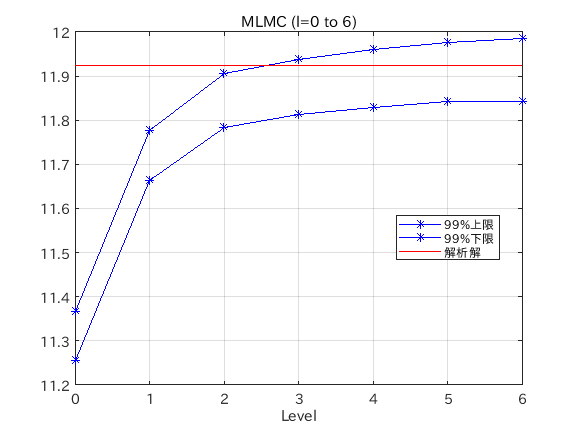

%推定区間の推定
Nt = 100;
alp = 0.01;

lowers = zeros(size(Nsims));
uppers = zeros(size(Nsims));

vss = zeros(Nt,size(Nsims,1));
for iloop = 1:Nt % 信頼区間計算のためのループ
    vs = zeros(size(Nsims));
    %　レベル 0での計算
    dt = T; 
    S1 = S0*ones(1,Nsims(1));
    for jloop = 1:1
        S1 = S1 + r*dt*S1 + sig*sqrt(dt)*S1.*randn(1,Nsims(1)); 
    end
    vs(1) = mean(exp(-r*T)*max(S1-K,0));

    % レベル 1から nlevelまでの計算
    for jloop = 1:nlevel
        Nstep = 2^(jloop);
        dt = T/Nstep; 
        dW = sqrt(dt)*randn(Nstep,Nsims(jloop));
        W = [zeros(1,Nsims(jloop));cumsum(dW)];
        % レベル l-1の計算
        S1 = S0*ones(1,Nsims(jloop));
        for kloop = 1:Nstep/2
            S1 = S1 + r*(2*dt)*S1 + sig*S1.*(W(2*kloop+1,:)-W(2*kloop-1,:));
        end
        % レベル lの計算
        S2 = S0*ones(1,Nsims(jloop));
        for kloop = 1:Nstep
            S2 = S2 + r*dt*S2 + sig*S2.*(W(kloop+1,:)-W(kloop,:));
        end
        vs(jloop+1) = mean(exp(-r*T)*(max(S2-K,0)-max(S1-K,0))); 
    end
    vss(iloop,:) = cumsum(vs)'; 
end

%信頼区間の計算
for iloop = 1:size(Nsims,1)
    rst = estConfidenceInterval(vss(:,iloop),alp);
    lowers(iloop) = rst.CILower;
    uppers(iloop) = rst.CIUpper;
end

nfig = 4;
figure(nfig);plot(nlevels,[uppers,lowers],'b*-');grid; title('MLMC (l=0 to ' + string(nlevel) + ')'); xlabel('Level'); hold on;
plot(nlevels,vana.callValue*ones(size(nlevels)),'r-'); legend('99%上限','99%下限','解析解','Location','best');
hold off;

### 課題 1

Antithetic Samplingを用いて、コールオプションの評価を行うプログラムを作成し、通常のシミュレーションの結果と比較せよ。

前提・条件はMLMCのオプション評価と同じとする。

解答例

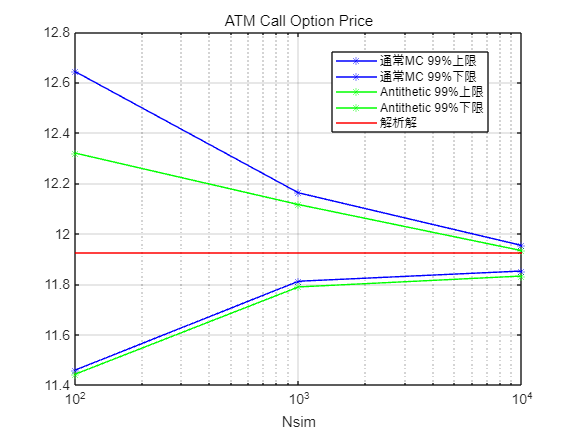

clear;
% 株価パラメータ
S0 = 100;
r = 0.05;
sig = 0.3;

% オプションパラメータ
T = 1; 
K = S0*exp(r*T); % ATM Strike

% シミュレーションパラメータ
Nsims = [100;1000;10000]; 
Nt = 100;
alp = 0.01;

Nstep = 50; % 一週間ステップ
dt = T/Nstep; 

% 通常のMC
lowers1 = zeros(size(Nsims));
uppers1 = zeros(size(Nsims));

% Antithetic Sampling
lowers2 = lowers1;
uppers2 = uppers1;

for iloop = 1:size(Nsims,1)
    Nsim = Nsims(iloop);
    vs1 = zeros(Nt,1);
    vs2 = zeros(Nt,1);
    for jloop = 1:Nt
        % 通常MC
        S1 = S0*ones(1,Nsim);
        dW1 = randn(Nstep,Nsim)*sqrt(dt); 
        % Antithetic Sampling
        S2 = S0*ones(1,Nsim);
        dWtmp = randn(Nstep,Nsim/2)*sqrt(dt);
        dW2 = [dWtmp,-dWtmp];
        for kloop = 1:Nstep
            % 通常MC
            S1 = S1 + r*S1*dt + sig*S1.*dW1(kloop,:);
            % Antithetic Sampling
            S2 = S2 + r*S2*dt + sig*S2.*dW2(kloop,:); 
        end
        vs1(jloop) = exp(-r*T)*mean(max(S1-K,0));
        vs2(jloop) = exp(-r*T)*mean(max(S2-K,0));
    end
    rst = estConfidenceInterval(vs1,alp);
    lowers1(iloop) = rst.CILower;
    uppers1(iloop) = rst.CIUpper;
    rst = estConfidenceInterval(vs2,alp);
    lowers2(iloop) = rst.CILower;
    uppers2(iloop) = rst.CIUpper;
end
% 解析解
vana = bsModelCallPut(S0,r,sig,T,K);
vanas = vana.callValue*ones(size(Nsims));

nfig = 5; 
figure(nfig);semilogx(Nsims,[uppers1,lowers1],'b*-'); grid; xlabel('Nsim'); title('ATM Call Option Price');hold on;
semilogx(Nsims,[uppers2,lowers2],'g*-');semilogx(Nsims,vanas,'r-'); 
legend('通常MC 99%上限','通常MC 99%下限','Antithetic 99%上限','Antithetic 99%下限','解析解','Location','best');hold off;

### 課題 2

上で示したMLMCのオプション評価のプログラムは重複が多く冗長である。関数を活用してプログラムをリファクタリングせよ、

＊リファクタリングとは、プログラムの機能を変えずにコーディングを改善することである。

### ローカル関数

Sobol列生成関数

function vfun = genSobolStreamFun(ndim)
    % Sobol列での乱択化ストリーム関数を返す
    arguments
        ndim (1,1) {mustBeInteger}
    end
    p = sobolset(ndim); 
    p = scramble(p,'MatousekAffineOwen');
    q = qrandstream(p); 
    
    vfun = @(Nsim) qrand(q,Nsim);
end